# 向下重采样测试

clear all;
orgInterval=0.01;     %原采样间隔
orgFs=1/orgInterval;  %原采率
orgCutFre=orgFs/2;    %原截止频率=1/2采样率
newInterval=0.02;     %新采样间隔
newFs=1/newInterval;  %新采样率
newOldRatio=newInterval/orgInterval;%新采样间隔/原采样间隔
orgLength=4096;       %原数据点数
newLength=floor(orgLength*orgInterval/newInterval);%新数据长度
zeta=newFs/(2*orgCutFre);%重采样的低通滤波器参数
n=0:orgLength-1;
t=n/orgFs;
xn0=sin(2*pi*1*t)+0.5*sin(2*pi*30*t);   %1和30Hz混合信号

%n1=0:newLength-1;
%newInterval=n1/newFs;


Nf=100; 
starPoint = floor(Nf/newOldRatio)+Nf+1;
endPoint  = newLength-floor(Nf/newOldRatio)-1;
x = zeros(starPoint,endPoint);
% 在信号处理领域，Sinc滤波器一个全部除去给定带宽之上的信号分量而只保留低频信号的理想电子滤波器。
% 在频域它的形状象一个矩形函数，在时域它的形状象一个Sinc函数。由于理想的Sinc滤波器（矩形滤波器）
% 有无限的延迟，所以现实世界中的滤波器只能是它的一个近似
for m=starPoint:endPoint
    %x(m)=0;
    starNPoint = floor(m*newOldRatio)-Nf;
    endNPoint = floor(m*newOldRatio)+Nf;
    for n=starNPoint:endNPoint
        tv = zeta*(m*newOldRatio-n);
        x(m)=x(m)+zeta*xn0(n)*sinc(tv);
    end
end
%xl=length(x);
n1=0:newLength-1;
tt1=n1/newFs;
%nn1=length(n1);

ntt1=length(tt1);
nx=length(x);
ty=0:0.001:orgLength*orgInterval-Nf/orgFs;
z=sin(2*pi*1*(ty+Nf/orgFs-0.01))+0.5*sin(2*pi*30*(ty+Nf/orgFs-0.01));

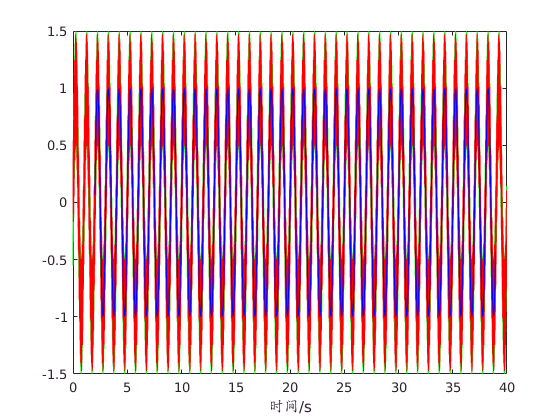

figure(1);
%subplot(2,1,1)
plot(ty,z,'g')
hold on
%红线是向下重采样的结果.在重采样的同时已实现了低通滤波
t100 = t(1+1:orgLength-Nf);
xn0100 = xn0(1+Nf:orgLength-1);
plot(t100,xn0100,'r');
hold on
%蓝线是向下重采样的结果.在重采样的同时已实现了低通滤波
tt150 = tt1(floor(Nf/newOldRatio)+Nf+1-newFs+1:newLength-floor(Nf/newOldRatio)-1-newFs+1);
x50 = x(floor(Nf/newOldRatio)+Nf+1:newLength-floor(Nf/newOldRatio)-1);
plot(tt150,x50,'b');
xlabel('时间/s')

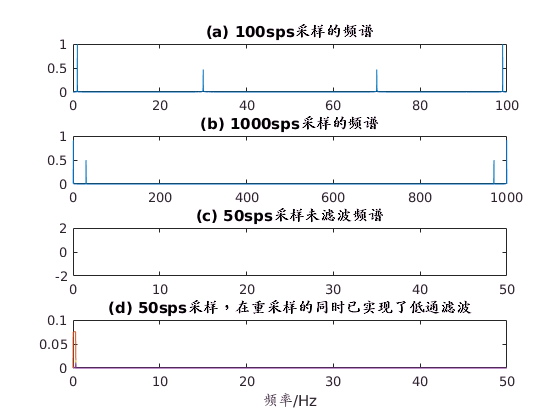

n=0:1:(orgLength-1);
f=n*orgFs/orgLength;
xn0fft=abs(fft(xn0,orgLength));
xn1=sin(2*pi*1*newInterval)+0.5*sin(2*pi*30*newInterval);

figure(2);
subplot(4,1,1);
plot(f,xn0fft*2/orgLength);
title('(a) 100sps采样的频谱')
zfft=abs(fft(z,32768));
n=0:1:(32768-1);
fz=n/(32768*0.001);
subplot(4,1,2);
plot(fz,2*zfft/32768);
title('(b) 1000sps采样的频谱');
subplot(4,1,4)
Nx=length(x);
xfft=abs(fft(x));
n=0:1:Nx-1;
fx=n*newFs/Nx;
plot(fx,2*xfft/Nx);
xlabel('频率/Hz');
title('(d) 50sps采样，在重采样的同时已实现了低通滤波');
subplot(4,1,3);
xn1fft=abs(fft(xn1));
fxn1=n1*newFs/newLength;
plot(fxn1,xn1fft*2/Nx);
title('(c) 50sps采样未滤波频谱');

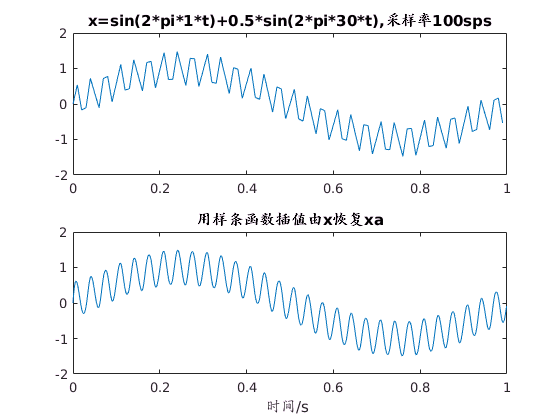

figure(3);
%用样条函数（spline)模拟信号恢复
%Dt=0.00005;t=-0.005:Dt:0.005;
subplot(2,1,1)
plot(t(1:100),xn0(1:100));
title('x=sin(2*pi*1*t)+0.5*sin(2*pi*30*t),采样率100sps');
subplot(2,1,2)
ty1=0:0.001:orgLength*orgInterval;
n=0:orgLength-1;
t=n/orgFs;
nty1=length(ty1);
nxn0=length(xn0);
nnt0=length(n*orgInterval);
xa=spline(n*orgInterval,xn0,ty1);
plot(ty1(1:1000),xa(1:1000))
title('用样条函数插值由x恢复xa');
xlabel('时间/s ');